# DSZOB, cvičenie 3.

## **Zadanie:**

## **Úloha 1 **

Vygenerujte si nasledujúce signály podľa predchádzajúcich cvičení:

- jednoduchý signál

- zložený signál (z troch jednoduchých signálov)

- jednoduchý signál so zníženou vzorkovacou frekvenciou s porušením Nyquistovho teorému

Pre vytvorené signály:

- Z daných signálov vyberte vhodnú vzorku 512 hodnôt, vypočítajte a vizualizujte Diskrétnu Fourierovu transformáciu podľa definície.

- Následne vypočítajte a vizualizujte príslušnú inverznú Fourierovu transformáciu. Aký je výstup? 

- Výpočet DFT a IDFT implementujte ako samostatné funkcie. 

- Výstup DFT vizualizujte, pričom spektrálne indexy prevediete na Hz. (fftshift a druhá polovica výstupu; prepočet od 0 do Fs/2 Hz, index-1)

- K signálom pripočítajte konštantnú hodnotu  (DC komponentu). Vypočítajte DFT a vizualizujte (originál výstup a aj pomocou fftshift) . Kde je možné vo vypočítanej DFT DC komponentu identifikovať?

## Pomôcka (definícia):

- počet prvkov vo vektore

- index spektrálnych koeficientov

- index vzorku vo vstupnom vektore (číslicový signál o dĺžke N)

## Pomôcka:

- pozor na názov funkcií

- fftshift()

- stem()

- abs()

- j

**Postup vhodne dokumentuje (Code/Text bloky)!**

**Pri vyzualizácií zamedzte zobrazovaniu upozornení.**

## **Riešenie:**

fs = 10000;
sx = 0:1/fs:3;
fs_lt_nyq = 8000;
sx_lt_nyq = (0:1/fs_lt_nyq:3);
sy1 = sin(2*pi*sx*1000);
sy2 = sin(2*pi*sx*2000) + sin(2*pi*sx*3000) + sin(2*pi*sx*4000);
sy3 = sin(2*pi*sx_lt_nyq*5000);
y1 = sy1(1:512);
y2 = sy2(1:512);
y3 = sy3(1:512);

## Jednoduchý signál:

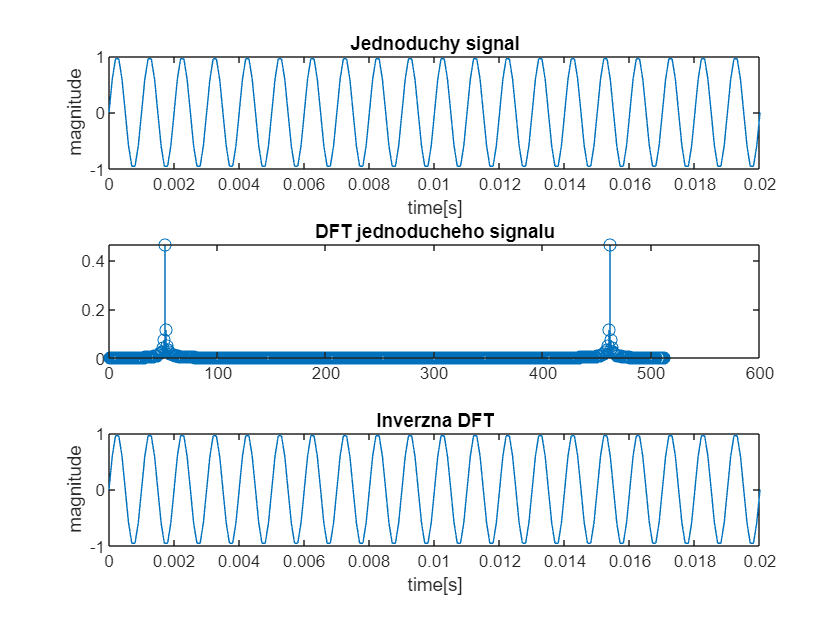

figure();
subplot(3,1,1);
plot(sx(1:512), y1)
title('Jednoduchy signal')
xlim([0 0.02])
xlabel('time[s]')
ylabel('magnitude')
subplot(3,1,2);
dft1 = custom_dft(y1);
stem(abs(dft1))
title('DFT jednoducheho signalu')
subplot(3,1,3);
dft1_i = custom_dft_i(dft1);
plot(sx(1:512), real(dft1_i))
title('Inverzna DFT')
xlim([0 0.02])
xlabel('time[s]')
ylabel('magnitude')

Použitím inverznej fourierovej transformácie dostávame pôvodný signál.

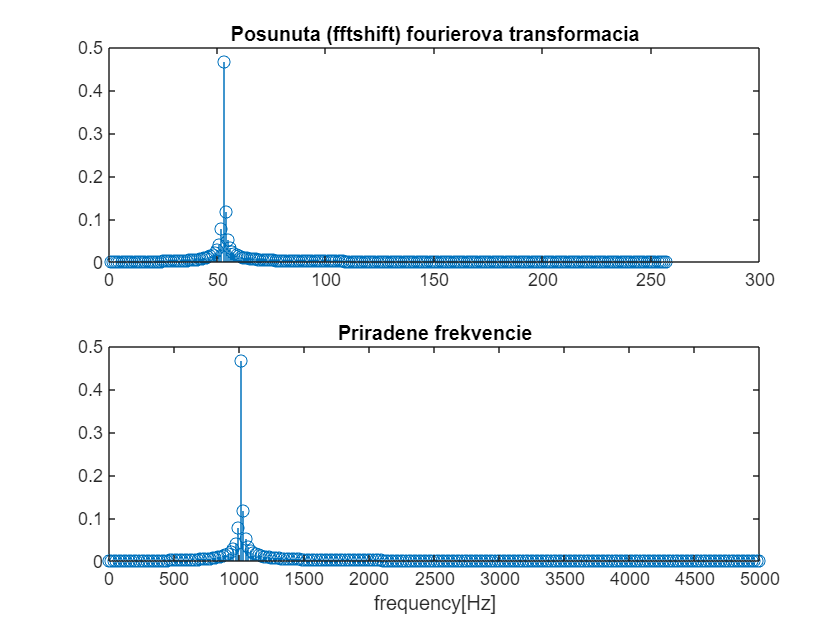

figure();
subplot(2,1,1);
dft1_shifted = fftshift(abs(dft1));
dft1_shifted = dft1_shifted(256:512);
stem(dft1_shifted)
title('Posunuta (fftshift) fourierova transformacia')
subplot(2,1,2);
stem(0:(fs/2)/256:fs/2, dft1_shifted)
title('Priradene frekvencie')
xlabel('frequency[Hz]')

Pomocou fourierovej transformácie vieme z frekvenčného spektra priradením konkrétnych frekvencii zistiť z akých reálnych frekvencii sa signál skladá. V tomto prípade to bolo 1000 Hz, čo je aj frekvencia, s ktorou bol signál generovaný.

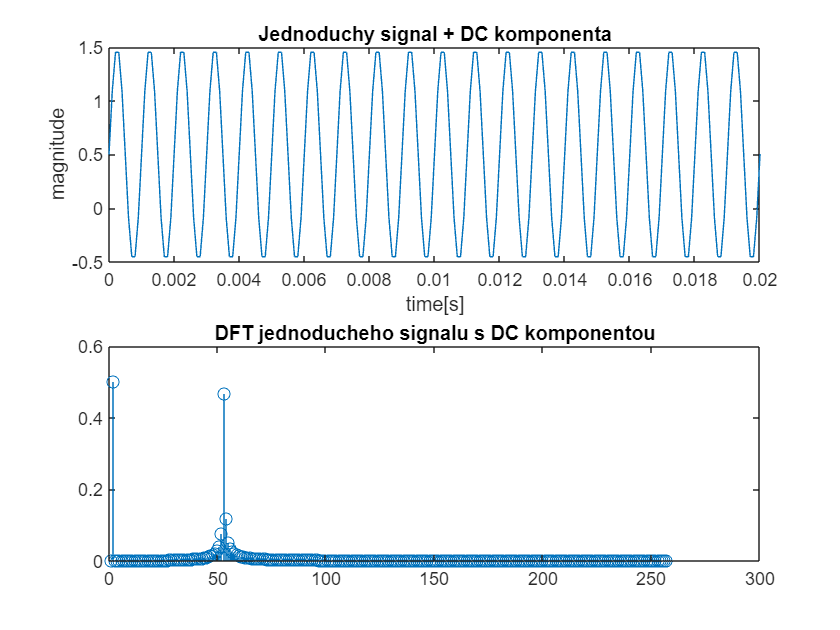

figure();
subplot(2,1,1);
y1_dc = y1 + 0.5;
plot(sx(1:512), y1_dc)
title('Jednoduchy signal + DC komponenta')
xlim([0 0.02])
xlabel('time[s]')
ylabel('magnitude')
subplot(2,1,2);
dft1_dc = fftshift(abs(custom_dft(y1_dc)));
stem(dft1_dc(256:512))
title('DFT jednoducheho signalu s DC komponentou')

Pridaním DC komponenty sa amplitúda/magnitúda posúva o jej hodnotu a na fourierovej transformácii je DC komponenta pozorovateľná prvou vychýlenou hodnotou.

## Zložený signál:

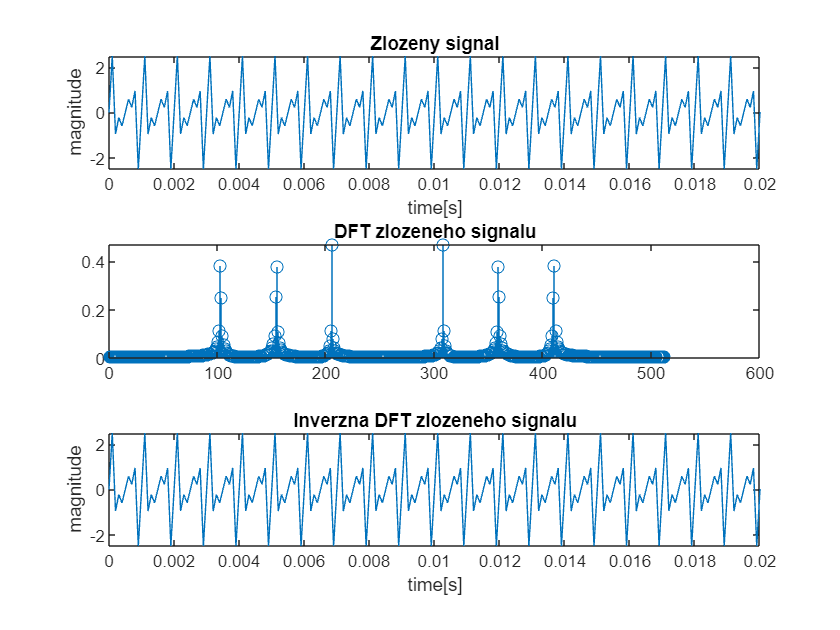

figure();
subplot(3,1,1);
plot(sx(1:512), y2)
xlim([0 0.02])
title('Zlozeny signal')
xlabel('time[s]')
ylabel('magnitude')
subplot(3,1,2);
dft2 = custom_dft(y2);
stem(abs(dft2))
title('DFT zlozeneho signalu')
subplot(3,1,3);
dft2_i = custom_dft_i(dft2);
plot(sx(1:512), real(dft2_i))
xlim([0 0.02])
title('Inverzna DFT zlozeneho signalu')
xlabel('time[s]')
ylabel('magnitude')

Pri inverznej fourierovej transformácii aj zloženého signálu dostanene opäť pôvodný signál.

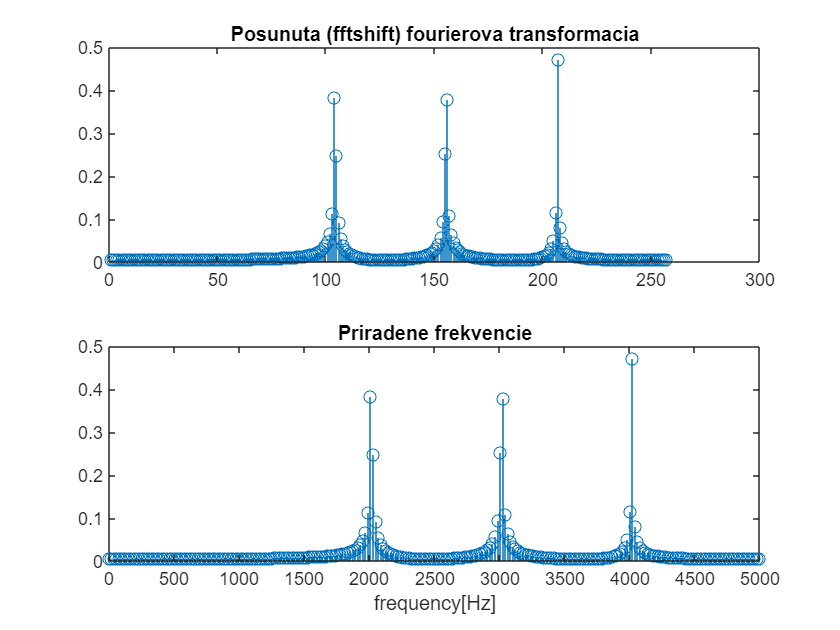

figure();
subplot(2,1,1);
dft2_shifted = fftshift(abs(dft2));
dft2_shifted = dft2_shifted(256:512);
stem(dft2_shifted)
title('Posunuta (fftshift) fourierova transformacia')
subplot(2,1,2);
stem(0:(fs/2)/256:fs/2, dft2_shifted)
title('Priradene frekvencie')
xlabel('frequency[Hz]')

Pomocou fourierovej transformácie vieme z frekvenčného spektra priradením konkrétnych frekvencii zistiť z akých reálnych frekvencii sa signál skladá. V tomto prípade to bolo 2000 Hz, 3000 HZ a 4000 HZ, čo sú aj frekvencie, s ktorými bol signál generovaný.

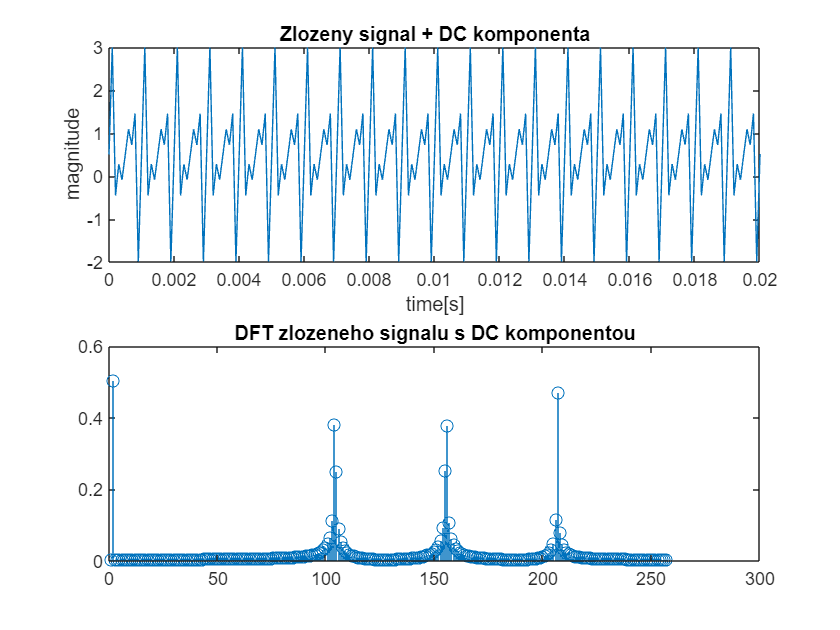

figure();
subplot(2,1,1);
y2_dc = y2 + 0.5;
plot(sx(1:512), y2_dc)
xlim([0 0.02])
title('Zlozeny signal + DC komponenta')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,1,2);
dft2_dc = fftshift(abs(custom_dft(y2_dc)));
stem(dft2_dc(256:512))
title('DFT zlozeneho signalu s DC komponentou')

Pridaním DC komponenty sa amplitúda/magnitúda posúva o jej hodnotu a na fourierovej transformácii je DC komponenta pozorovateľná prvou vychýlenou hodnotou.

## Jednoduchý signál porušujúci nyquistov teorém:

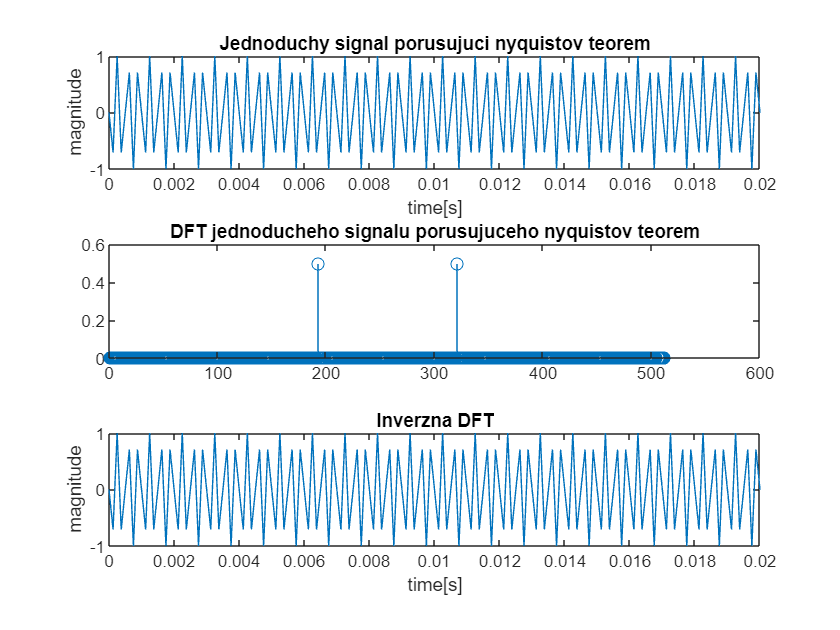

figure();
subplot(3,1,1);
plot(sx_lt_nyq(1:512), y3)
xlim([0 0.02])
title('Jednoduchy signal porusujuci nyquistov teorem')
xlabel('time[s]')
ylabel('magnitude')
subplot(3,1,2);
dft3 = custom_dft(y3);
stem(abs(dft3))
title('DFT jednoducheho signalu porusujuceho nyquistov teorem')
subplot(3,1,3);
dft3_i = custom_dft_i(dft3);
plot(sx_lt_nyq(1:512), real(dft3_i))
xlim([0 0.02])
title('Inverzna DFT')
xlabel('time[s]')
ylabel('magnitude')

Aj pre signál porušujúci nyquistov teorem dostaneme inverznou transformáciou pôvodný signál.

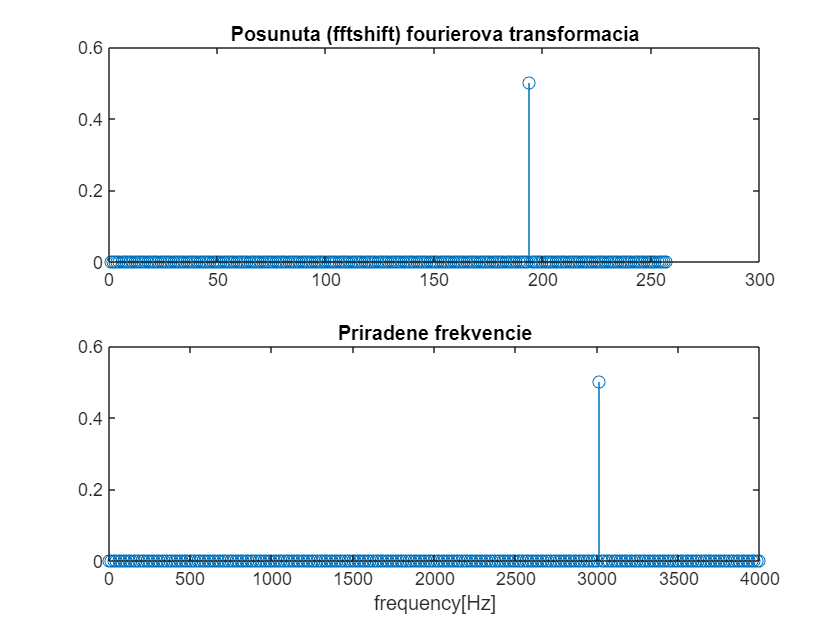

figure();
subplot(2,1,1);
dft3_shifted = fftshift(abs(dft3));
dft3_shifted = dft3_shifted(256:512);
stem(dft3_shifted)
title('Posunuta (fftshift) fourierova transformacia')
subplot(2,1,2);
stem(0:(fs_lt_nyq/2)/256:fs_lt_nyq/2, dft3_shifted)
title('Priradene frekvencie')
xlabel('frequency[Hz]')

Pre signál porušujúci nyquistov teorém fourierova transformácia neposkytuje správne frekvenčné spektrum keďže podľa nej bola primárna frekvencie 3000 Hz, ale signál bol v skutočnosti generovaný s frekvenciou 5000 Hz.

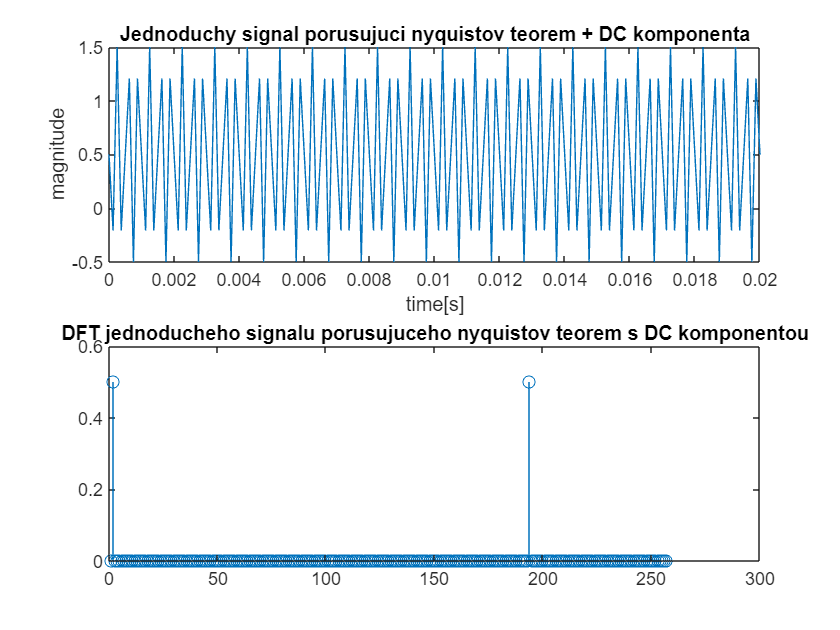

figure();
subplot(2,1,1);
y3_dc = y3 + 0.5;
plot(sx_lt_nyq(1:512), y3_dc)
xlim([0 0.02])
title('Jednoduchy signal porusujuci nyquistov teorem + DC komponenta')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,1,2);
dft3_dc = fftshift(abs(custom_dft(y3_dc)));
stem(dft3_dc(256:512))
title('DFT jednoducheho signalu porusujuceho nyquistov teorem s DC komponentou')

Aj pre signál porušujúci nyquistov teorém je možné po fourierovej transformácii pozorovať DC komponentu ako prvú hodnotu vektora.

## **Úloha 2 **

Vygenerujte si jednoduchý signál. Pre okienko veľkosti 512 a okienko dĺžky, ktoré nezachytí ani celú základnú periódu (je príliš krátke) vypočítajte a vizualizujte DFT. Sú výstupné spektrá zhodné? Prečo je to tak?

## **Riešenie:**

fs = 2000;
sx = 0:1/fs:1;
sy = sin(2*pi*sx*100);
x1 = sx(1:512);
y1 = sy(1:512);
x2 = sx(1:16);
y2 = sy(1:16);

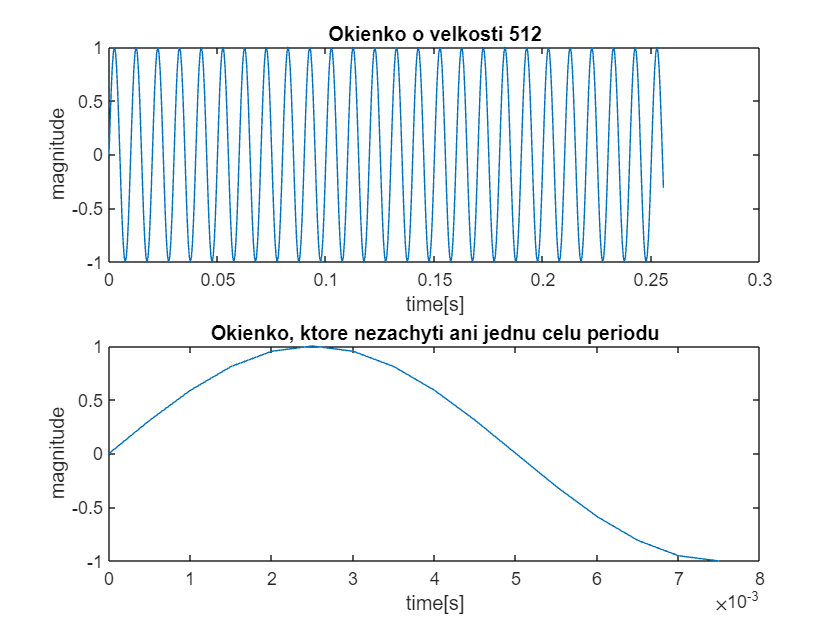

figure();
subplot(2,1,1);
plot(x1,y1)
title('Okienko o velkosti 512')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,1,2);
plot(x2,y2)
title('Okienko, ktore nezachyti ani jednu celu periodu')
xlabel('time[s]')
ylabel('magnitude')

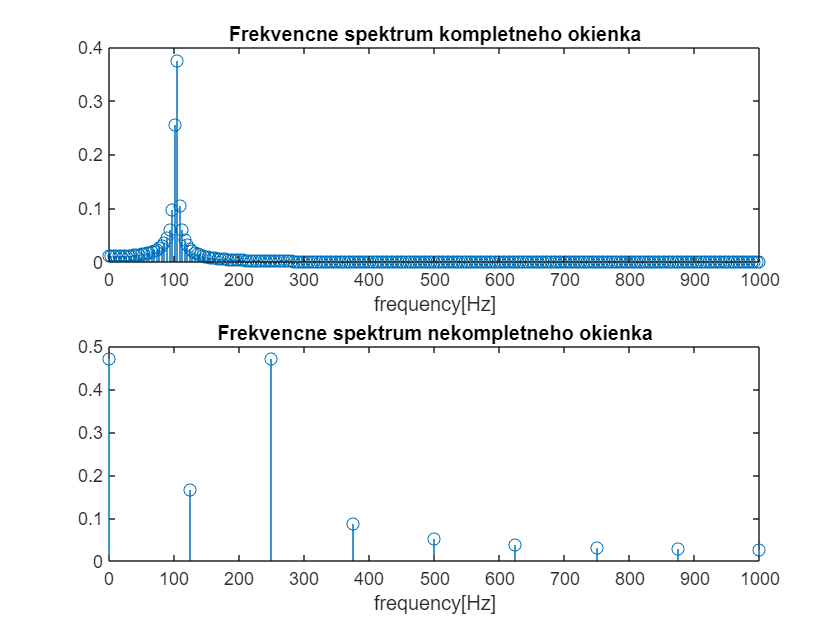

figure();
subplot(2,1,1);
dft1 = custom_dft(y1);
dft1 = fftshift(abs(dft1));
dft1 = dft1(256:512);
stem(0:(fs/2)/256:fs/2, dft1)
title('Frekvencne spektrum kompletneho okienka')
xlabel('frequency[Hz]')
subplot(2,1,2);
dft2 = custom_dft(y2);
dft2 = fftshift(abs(dft2));
dft2 = dft2(8:16);
stem(0:(fs/2)/8:fs/2, dft2)
title('Frekvencne spektrum nekompletneho okienka')
xlabel('frequency[Hz]')

Pre okienko, ktoré nezachytáva ani jednu kompletnú periódu nie je možné fourierovou transformáciou správne určiť frekvenčné spektrum alebo konkrétnu primárnu frekvenciu. Spektrum pre nekompletné okienko navyše vykazje prítomnosť DC komponentz, ktorá však v pôvodnom signále nie je.

## **Úloha 3 **

Vygenerujte si jednoduchý párny a nepárny signál (sin a cos). Pre tieto signály vyberte ľubovoľné okienko tak, aby v rámci okienka vyšiel celočíselný počet periód (napríklad tón 430.664062 pre 5 periód pri veľkosti okienka 512). Ako sa prejaví párny a nepárny signál v reálnej a imaginárnej zložke?

## **Riešenie:**

fs = 1024;
sx = 0:1/fs:3;
x = sx(1:512);
sy_sin = sin(2*pi*sx*16);
y_sin  = sy_sin(1:512);
sy_cos = cos(2*pi*sx*16);
y_cos  = sy_cos(1:512);

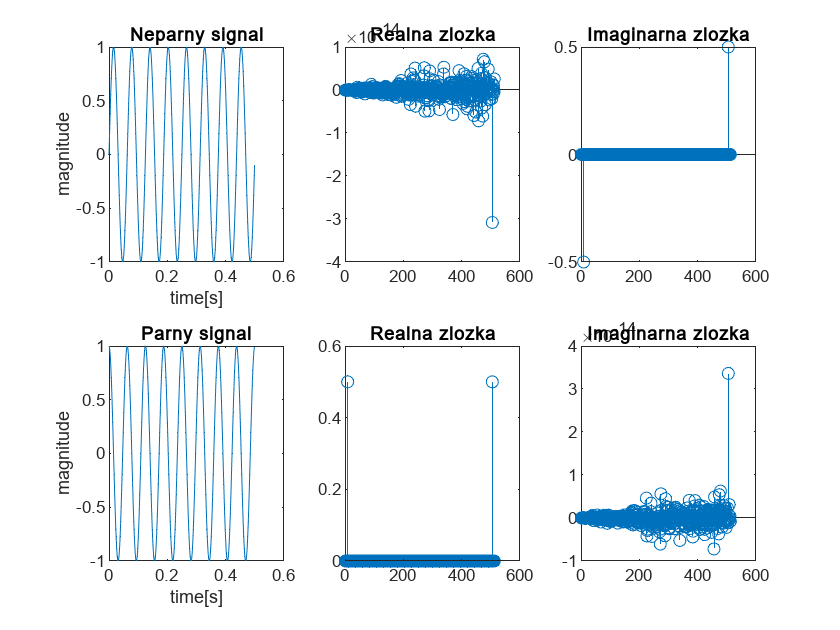

figure();
subplot(2,3,1);
plot(x,y_sin)
title('Neparny signal')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,3,2);
dft = custom_dft(y_sin);
stem(real(dft))
title('Realna zlozka')
subplot(2,3,3)
stem(imag(dft))
title('Imaginarna zlozka')

subplot(2,3,4);
plot(x,y_cos)
title('Parny signal')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,3,5);
dft = custom_dft(y_cos);
stem(real(dft))
title('Realna zlozka')
subplot(2,3,6);
stem(imag(dft))
title('Imaginarna zlozka')

Pri použití párnej funkcie sú hodnoty v reálnej a imaginárnej rovine po fourierovej transformácii naopak ako pri použití nepárnej funkcie.

## **Úloha 4 **

Nahrajte svoj hlas (akékoľvek slová) po dobu troch sekúnd pri vzorkovacej frekvencií 44100Hz.

- Nahraný zvuk vizualizujte.

- Na základe vizualizácie vyberte vhodné okienko (ktoré zachytí váš hlas a nie len šum a "ticho") o dĺžke 1024, ktoré taktiež vizualizujete.

- Vypočítajte a vizualizujte DFT (pomocou funkcie plot). 

- Aká je primárna frekvencia (frekvencia s maximálnou amplitúda z vypočítaného DFT) v danom výseku?  - Odpoveď udajte v Hz.

Pomôcka:

- [https://www.mathworks.com/help/matlab/import_export/record-and-play-audio.html](https://www.mathworks.com/help/matlab/import_export/record-and-play-audio.html)

fs = 44100;
recorder = audiorecorder(fs,8,1);
recordblocking(recorder,3);
y = getaudiodata(recorder)';
x = 0:1/fs:3;
x = x(1:132300);


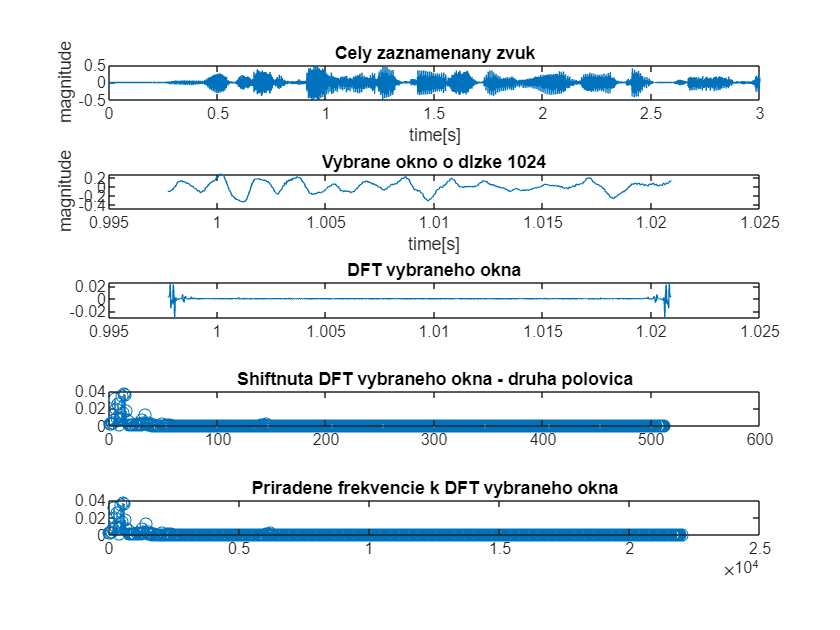

figure();
subplot(5,1,1);
plot(x,y)
title('Cely zaznamenany zvuk')
xlabel('time[s]')
ylabel('magnitude')
subplot(5,1,2);
x2 = x(44000:45023);
y2 = y(44000:45023);
plot(x2,y2)
title('Vybrane okno o dlzke 1024')
xlabel('time[s]')
ylabel('magnitude')
subplot(5,1,3);
dft = custom_dft(y2);
plot(x2, real(dft))
title('DFT vybraneho okna')
subplot(5,1,4);
stem(abs(dft(1:512)))
title('Shiftnuta DFT vybraneho okna - druha polovica')
subplot(5,1,5);
x_hz = 0:(fs/2)/512:fs/2;
x_hz = x_hz(1:512);
stem(x_hz, abs(dft(1:512)))
title('Priradene frekvencie k DFT vybraneho okna')

[M,I] = max(abs(dft(1:512)));
x_hz(I)

ans = 559.8633

Pomocou funkcie max dostaneme hodnotu a index, kde je najdominantnejšia/primárna frekvencia. Keď tento index použijeme na prístup do vektora frekvencii dostaneme hodnotu primárnej frekvencie. Táto je 559,8633 Hz.

## Priestor pre vaše funkcie:

function f = custom_dft(y)
    M = length(y);
    f = zeros(1, M);
    e = exp(1);    
    
    for u = 0:M-1
        t = 0;
        for x = 0:M-1
            t = t + y(x+1)*e^((-j)*2*pi*x*u / M);
        end
        t = t/M;
        f(u + 1) = t;
    end
end


function f = custom_dft_i(y)
    M = length(y);
    f = zeros(1, M);
    e = exp(1);    
    
    for u = 0:M-1
        t = 0;
        for x = 0:M-1
            t = t + y(x+1)*e^(j*2*pi*x*u / M);
        end
        f(u + 1) = t;
    end
end
